# Plot time course maps of outbreak in urban forest using raster maps and scatter plot

Generates spatial maps of disease progress which are stored as png. Then can choose to import pngs and create a video (avi file), plot all maps, plot by garden/road/all

%clear all
%clear vars
close all
TopPath = 'D:/Cerian/OneDrive - University of Cambridge/UrbanTreeModel/ModelCodeForPublic2023/UrbanEpidemicModel2023';

addpath([TopPath,'/core']);
addpath([TopPath,'/plotting']);
addpath([TopPath,'/dataPrepare/SyntheticLandscapes']);
addpath([TopPath,'/plot_functions'])

To run this code you will need to download the following functions from Matlab file exchange (which I have stored in a folder called MatlabFileExchange)

[ColorBrewer: Attractive and Distinctive Colormaps - File Exchange - MATLAB Central (mathworks.com)](https://uk.mathworks.com/matlabcentral/fileexchange/45208-colorbrewer-attractive-and-distinctive-colormaps?s_tid=srchtitle)

[.xyz file functions - File Exchange - MATLAB Central (mathworks.com)](https://uk.mathworks.com/matlabcentral/fileexchange/56414-xyz-file-functions?s_tid=ta_fx_results)


addpath('D:/Cerian/OneDrive - University of Cambridge/MatlabFileExchange/DrosteEffect-BrewerMap-5b84f95');
addpath('D:/Cerian/OneDrive - University of Cambridge/MatlabFileExchange/xyzFileOperations');

## Edit to save figures in a different place

first time you run you either need to make a new directory in file explorer or uncomment the mkdir command below.

% where want figures to be written to
if  exist([TopPath,'/SimulationOutput/PlotsOfSimulation'],'dir') == 0
mkdir(TopPath,'/SimulationOutput/PlotsOfSimulation');
end
PathToFigs  = [TopPath,'/SimulationOutput/PlotsOfSimulation']; 
% what to do with figs


# EDIT TO GET DESIRED OUTPUT

#### load model output: first point in direction of output for required landscape and parameter set

SimulationOutputToPlot = 'ParGp1Matern1Start_3' %'ParGp1All1Start_3';

SimulationOutputToPlot = 'ParGp1Matern1Start_3'

cd([TopPath,'/SimulationOutput/',SimulationOutputToPlot])
timeStep = [1 10:10:80];
runNumber = 1;

### Colormaps

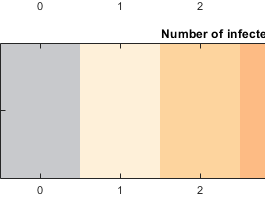

ColAll = [136 204 238]./255;
ColRoad = [170 68 153]./255;
ColPark = [17 119 51]./255;
ColRoadMap = [200 201 204]./255;
BackgrdColMap = [ 0 0 0; ColRoadMap];
UpperLimit = 6;
ColInfectRoadMap  = brewermap(UpperLimit,'OrRd');
LightGreen = [0.6 0.9412 0.6235];
ColRoadMap = [200 201 204]./255;
ColInfectRoadMap = [ColRoadMap; ColInfectRoadMap];
ColInfectGardenMap = brewermap(UpperLimit,'GnBu');
ColInfectGardenMap = [ColRoadMap; ColInfectGardenMap];

t = tiledlayout(2,1,'Padding','none');
ax1 = nexttile;
imagesc(0:UpperLimit);
ax1.XTickLabel = {'0','1','2','3','4','5','\geq 6'};
ax1.YTickLabel = {};
colormap(ax1,ColInfectGardenMap)
title('Number of infected trees in Garden Patch')
ax2 = nexttile; 
Im2 = imagesc(0:UpperLimit);
colormap(ax2,ColInfectRoadMap)
title('Number of infected trees on Road Patch')
ax2.XTickLabel = {'0','1','2','3','4','5','\geq 6'};
ax2.YTickLabel = {};

t.Title.String = SimulationOutputToPlot;
t.Title.FontWeight = 'bold';
t.Subtitle.String = ['Run number = ',num2str(runNumber)];
fignum = 1;

t.Units = 'pixels';
exportgraphics(t,[PathToFigs,'/NextFig',num2str(fignum),'All.png'],'Resolution',150)

#### now select which output

1 = multiple replicates

2 = one replicate

OutputType = 2; %1 =  'multiRun'; 2 = singleRun


if OutputType == 1
load('multiRunStatsSimout.mat')
urbanLandscape = simout.opts.LandscapeName
NumReps = simout.NumRuns;
AvgInfectedGardenTreesByTime = simout.IoutputgNumTrees./NumReps;
AvgInfectedRoadTreesByTime = simout.IoutputNumTrees./NumReps;

elseif OutputType == 2
    load(['simOut_',num2str(runNumber),'.mat'])
urbanLandscape = simout.opts.LandscapeName
%NumReps = simout.NumRuns;
AvgInfectedGardenTreesByTime = simout.Ioutputg;
AvgInfectedRoadTreesByTime = simout.Ioutput;
end 

urbanLandscape = 'synth_Matern_1_UrbanLandscape'

### Load landscape data and convert grid locations to matrix

load([urbanLandscape '.mat'])
[XGridLoc,YGridLoc,NumParkTrees] = xyz2grid(urbanLandscape.gridcenters(:,1),urbanLandscape.gridcenters(:,2),simout.parkpopulation);
XGridLocList = XGridLoc(:); 
YGridLocList = YGridLoc(:); 
XRoadLocList = urbanLandscape.roadcenters(:,1); 
YRoadLocList = urbanLandscape.roadcenters(:,2); 

reformat data

NumParkTreesList = NumParkTrees(:);
NumRoadTreesList = simout.roadpopulation;
maxTreesinParkCell = max(NumParkTreesList);
maxTreesinRoadCell = max(NumRoadTreesList);
LocWithParkTree = find(NumParkTreesList>0);
LocWithRoadTree = find(NumRoadTreesList>0);

## Run generation of figures

If want to generate images for parks and roads separately set SeparateGraphsForRoadPark

to any value greater than 0

tilenum = 0

tilenum = 0

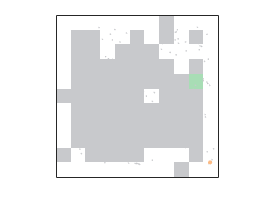

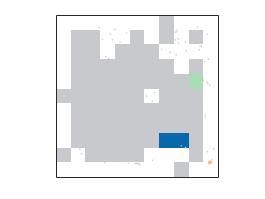

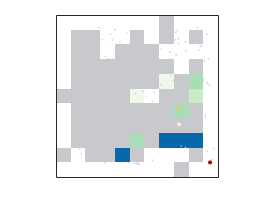

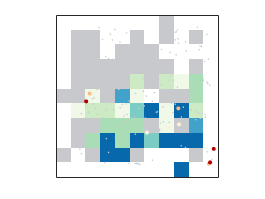

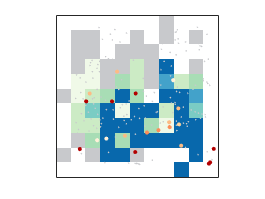

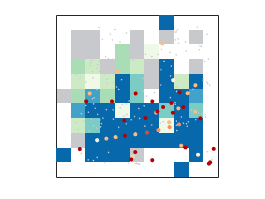

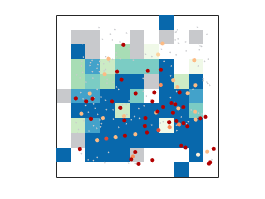

% if want to generate images for parks and roads separately set SeparateGraphsForRoadPark
% to any value greater than 0
SeparateGraphsForRoadPark = 0; 
MaximumInfected = 1; % proportion of trees in patch infected over which colormap is fixed
for i = 1:numel(timeStep)
   clf
    tilenum = i;
   RoadOn = 1; ParkOn = 1;
   fignum = tilenum+1; % first figure is title slide
   FxPlotRasterOfCasesAxesv2(timeStep(i),XGridLoc,YGridLoc,AvgInfectedGardenTreesByTime./NumParkTreesList,AvgInfectedRoadTreesByTime./NumRoadTreesList,NumParkTrees,XRoadLocList,YRoadLocList, LocWithRoadTree, BackgrdColMap,ColInfectGardenMap,ColInfectRoadMap,fignum,RoadOn,ParkOn,MaximumInfected,PathToFigs);
    clf
    
    if SeparateGraphsForRoadPark > 0
   RoadOn = 1; ParkOn = 0;
   fignum = numel(timeStep)+tilenum;
   FxPlotRasterOfCasesAxesv2(timeStep(i),XGridLoc,YGridLoc,AvgInfectedGardenTreesByTime./NumParkTreesList,AvgInfectedRoadTreesByTime./NumRoadTreesList,NumParkTrees,XRoadLocList,YRoadLocList, LocWithRoadTree, BackgrdColMap,ColInfectGardenMap,ColInfectRoadMap,fignum,RoadOn,ParkOn,MaximumInfected,PathToFigs);
clf
   RoadOn = 0; ParkOn = 1;
   fignum = 2.*numel(timeStep)+tilenum;
  FxPlotRasterOfCasesAxesv2(timeStep(i),XGridLoc,YGridLoc,...
      AvgInfectedGardenTreesByTime./NumParkTreesList,AvgInfectedRoadTreesByTime./NumRoadTreesList,NumParkTrees,XRoadLocList,YRoadLocList, LocWithRoadTree, BackgrdColMap,ColInfectGardenMap,ColInfectRoadMap,fignum,RoadOn,ParkOn,MaximumInfected,PathToFigs);
    end

end

#### Load figures and plot in a grid: All, Road, Garden

To run this bit of code set PlotGridFigs to any positive value

PlotGridFigs = 0;
if PlotGridFigs > 0
 tiledlayout(3,numel(timeStep),"TileSpacing","none")
 for i = 1:numel(timeStep)
     
     tilenum = i;
     fignum = tilenum;
     nexttile(fignum)
     A = imread([PathToFigs,'/NextFig',num2str(fignum),'All.png']);
     imshow(A,'border','tight')
     title(['Time step ',num2str(timeStep(i))])
     
     fignum = numel(timeStep)+tilenum;
     nexttile(fignum)
     A = imread([PathToFigs,'/NextFig',num2str(fignum),'Road.png']);
     imshow(A,'border','tight')
     
     fignum = 2.*numel(timeStep)+tilenum;
     nexttile(fignum)
     A = imread([PathToFigs,'/NextFig',num2str(fignum),'Garden.png']);
     imshow(A,'border','tight')
     
 end
end

#### Load figures and plot in a grid: All only

Only plots if set PlotAllTrees to some positive value

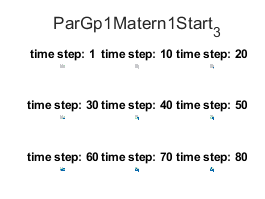

PlotAllTrees = 1;
if PlotAllTrees > 0 
tiledlayout(3,numel(timeStep),"TileSpacing","none")

figure
 for i = 1:numel(timeStep)
     
     tilenum = i;
     fignum = tilenum+1;
     nexttile(fignum)
     A = imread([PathToFigs,'/NextFig',num2str(fignum),'All.png']);
     imshow(A,'border','tight')
     title(['time step: ', num2str(timeStep(i))])
     
     
 end
 sgtitle(SimulationOutputToPlot)
end

Run and save movie of output

movieon = 0;
if movieon > 0
images    = cell(numel(timeStep)+1,1);
 NumImages = numel(timeStep)+1;
 v = VideoWriter(['AllTreesRun',num2str(runNumber),'.avi'],'Uncompressed AVI');
 v.FrameRate = 8;
     open(v);
     ii = 1;
     MapTree = imread([PathToFigs,'/NextFig',num2str(ii),'All.png']);
     MapTreeSc = imresize(MapTree,[539,540]);
     for repeatImage = 1:4
     writeVideo(v,im2frame(MapTreeSc))
     end
 for ii= 2:NumImages
     MapTree = imread([PathToFigs,'/NextFig',num2str(ii),'All.png']);
       MapTreeSc = imresize(MapTree,[539,540]);
     writeVideo(v,im2frame(MapTreeSc))
 end
 close(v);
 %  implay(['AllTreesRun',num2str(runNumber),'.avi']);

toc
end

 load chirp
%sound(y,Fs/3)